birdID = 'TURMER';
filename = 'common_blackbird_long_2.wav';

[cbAudio, cbFs] = audioread(filename);
% convert to mono
cbAudio = mono(cbAudio);

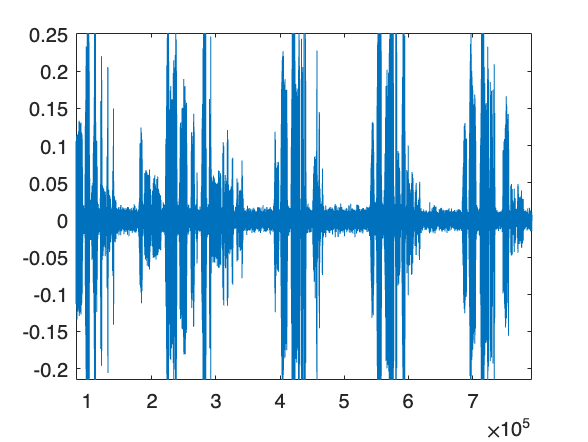

plot(cbAudio);

% trim the first bit of silence
cbAudio = cbAudio(50000:end);
% normalize
% cbAudio = normalize(cbAudio)/8;

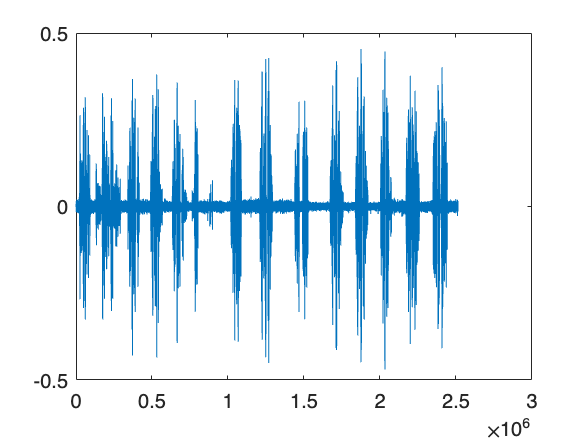

plot(cbAudio);

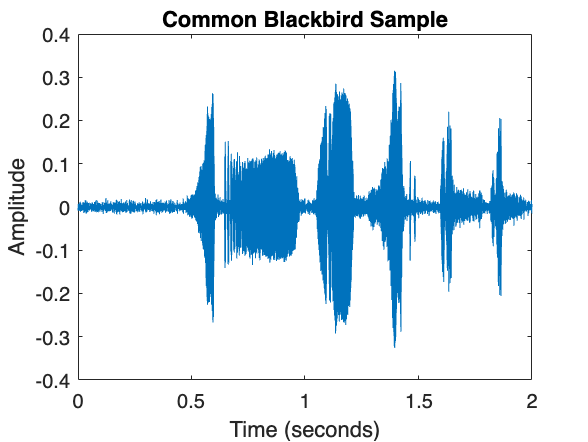

sampledCbAudio = cbAudio(1:2*cbFs);
plot((0:numel(sampledCbAudio)-1)/cbFs,sampledCbAudio)
title('Common Blackbird Sample')
xlabel('Time (seconds)')
ylabel('Amplitude')

sound(sampledCbAudio,cbFs)

cb = cbAudio;
fs = cbFs;

frameSizeMs = 3;
frameSize = floor((3/1000)*fs);
overlapSize = frameSize/2;
frames = buffer(cb,frameSize,overlapSize,'nodelay');

window = hann(frameSize);
windowedFrames = frames .* window;

energy = sum(windowedFrames.^2,1);
energyDb = 10 * log10(energy);
% normalize to 0db
energyDb = energyDb - max(energyDb);

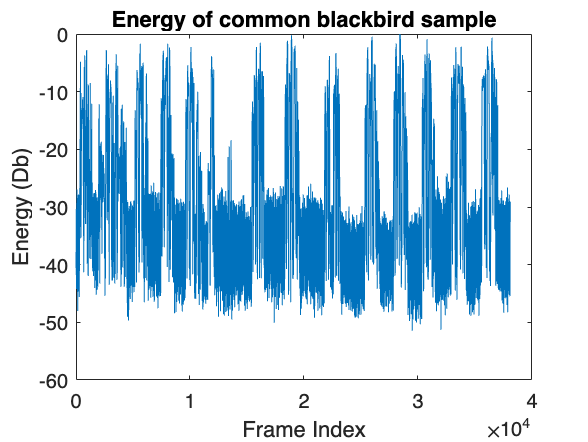

f1 = figure;
plot(energyDb)
title('Energy of common blackbird sample')
xlabel('Frame Index')
ylabel('Energy (Db)')

initNoiseDb = min(energyDb);
initThreshDb = initNoiseDb/2;
numFrames = size(windowedFrames,2);

noiseDb = initNoiseDb;
threshDb = initThreshDb;
onsets = zeros(1,numFrames);
offsets = zeros(1,numFrames);
sigMarkers = zeros(1,numFrames);
sigMarker = false;
for i = 1:numFrames
    frameEnergy = energyDb(1,i);
    if frameEnergy > threshDb
        sigMarkers(i) = 1;
        if ~sigMarker
            onsets(i) = 1;
            sigMarker = true;
        end
    else
        if sigMarker
            offsets(i) = 1;
            sigMarker = false;
        else
            if i > 1
                processedNonSyllableFrames = find(~sigMarkers(:,1:i-1));
                noiseDb = mean(energyDb(processedNonSyllableFrames));
                threshDb = noiseDb/2;
            end
        end
    end
end

hold on
plot(find(onsets),-10,'gx','MarkerSize', 10)
plot(find(offsets),-10,'rx','MarkerSize', 10)
hold off

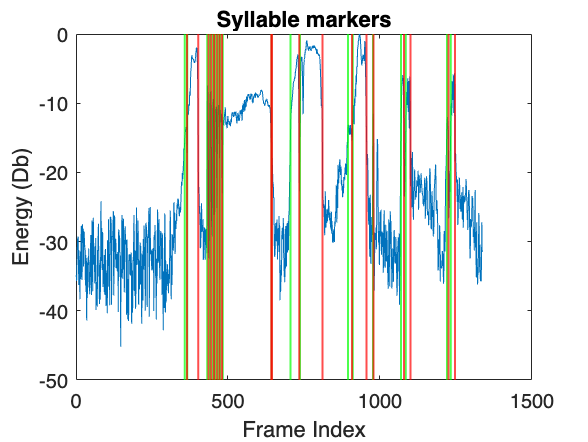

figure(f1), hold on
xline(find(onsets),'g','LineWidth', 1)
xline(find(offsets),'r','LineWidth', 1)
title('Syllable markers')
xlabel('Frame Index')
ylabel('Energy (Db)')
hold off

% syllable merging
mergeThreshMs = 15;
mergeThreshFrames = (mergeThreshMs*2)/frameSizeMs;

mergedSm = sigMarkers;
mergedOff = offsets;
mergedOns = onsets;

onsetIndices = find(onsets);
offsetIndices = find(offsets);
% if same number of offsets as onsets then we can ignore last offset
if numel(onsetIndices) == numel(offsetIndices)
    offsetIndices = offsetIndices(1:end-1);
end
syllableDists = onsetIndices(2:end)-offsetIndices;
mergeCandidateIndices = find(syllableDists <= mergeThreshFrames);
for ii = mergeCandidateIndices
    oi = offsetIndices(ii);
    ol = oi+syllableDists(ii);
    mm = oi:ol;
    mergedSm(mm) = 1;
    mergedOff(oi) = 0;
    mergedOns(ol) = 0;
end

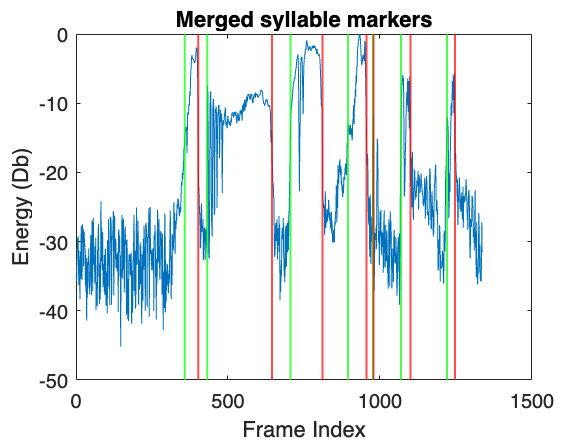

plot(energyDb);
hold on
xline(find(mergedOns),'g','LineWidth', 1)
xline(find(mergedOff) ,'r','LineWidth', 1)
title('Merged syllable markers')
xlabel('Frame Index')
ylabel('Energy (Db)')
hold off

markedSamples = zeros(size(cb));
for ii = find(mergedSm)
    ss = (ii - 1) * overlapSize + 1;
    se = ss + frameSize - 1;
    markedSamples(ss:se) = 1;
end

syllableBoundaries = find(diff(markedSamples) ~= 0) + 1;

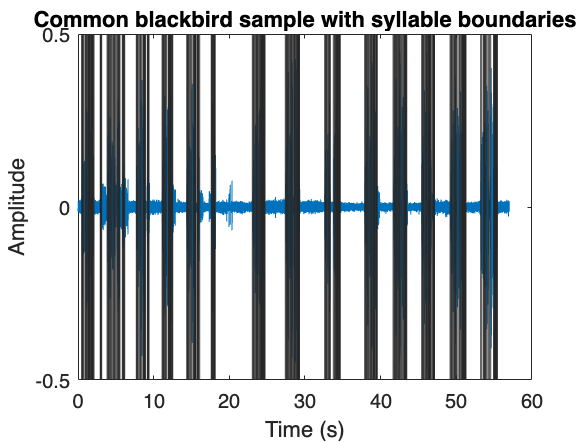

plot((0:numel(cb)-1)/fs,cb)
hold on
xline(syllableBoundaries/fs,'LineWidth', 1)
title('Common blackbird sample with syllable boundaries')
xlabel('Time (s)')
ylabel('Amplitude')
hold off

minimumSyllableThreshMs = 5;
minimumSyllableThreshFrames = minimumSyllableThreshMs * fs / 1000;
syllables = {};
for ii = 1:2:numel(syllableBoundaries)
    if ii+1 > numel(syllableBoundaries)
        break
    end
    st = syllableBoundaries(ii);
    en = syllableBoundaries(ii+1);
    if en-st < minimumSyllableThreshFrames
        continue
    end
    syllables = [syllables;{cb(st:en)}];
end

randSamp = randi(numel(syllables));
syllable = cell2mat(syllables(randSamp));
sound(syllable,fs);

for ii = 1:numel(syllables)
    syllable = cell2mat(syllables(ii));
    sound(syllable,fs); 
    pause(0.5);
end

for ii = 1:numel(syllables)
    syllable = cell2mat(syllables(ii));
    [~,wavFile,~] = fileparts(filename);
    fname = sprintf('./samples/syllables/%s/%s_%d.wav',birdID,wavFile,ii);
    audiowrite(fname,syllable,fs);
end